**MEAN FILTER**

Mean filter görüntüyü gürültülerden arındırma için kullanılan bir tür filtreleme yöntemidir.

Bu yöntemde filtreleme için n*n (n = 2k+1, k sıfırdan farklı bir doğal sayı) boyutunda bir çekirdek (kernel) kullanılır. Bu çekirdek görselin matris hali üzerindeki her elemanın alacağı değeri belirlemek için kullanılır. Örneğin 3*3'lük bir çekirdek kullanılıyorsa, görseldeki her 3*3'lük kısım 1/9 ile çarpılır.

Bunun için MATLAB üzerinde *filter() *metodu bulunmaktadır ancak bu uygulamada metotlar kullanılmayacaktır.

Biz de bir görüntüyü blurlaştırmak için ilk olarak resmi MATLAB içerisine dahil edelim. Ardından bu işlemin gereğinden fazla GPU harcamasını önlemek için *rgb2gray() *fonksiyonunu kullanarak resmi ton ve doygunluk unsurlarından arındıralım.

colored_img = imread("lena.png");
img = rgb2gray(colored_img);

Daha sonra resme mean filter uygulayabilmek için yeni bir değişken oluşturalım. Bunun için ilk başta resmin boyutunu öğreneceğiz, daha sonrasında bu boyutlarda bir sıfır matris oluşturacağız.

[m,n] = size(img);
output = zeros(m,n);

Mean filter uygulama aşamasına geçmeden önce çekirdek boyutunu belirleyelim. Belirleyeceğimiz bu boyut oluşturduğumuz algoritma gereği merkezin kenara olan uzaklığını verecektir. Yani oluşturduğumuz radius değişkeni eğer 2 ise (2n+1) formülünden 5*5'lik bir çekirdek kulanıyoruz demektir. Çekirdek boyutu arttıkça görüntüdeki blurlaşma da artacaktır.

radius = 20;

Radius değerini belirledikten sonra bir for döngüsü ile img matrisinin tüm değerleri içerisinde gezinelim. Daha sonrasında çekirdek boyutunda geçici matrisler oluşturalım. Bu matrislerin ortalama değerini aldıktan sonra asıl sonuç almak istediğimiz matrisin içerisine atayalım. 

Burada dikkat edilmesi gereken nokta şu ki elimizdeki görsel her zaman ve hatta çoğu zaman bir kare matris oluşturmayabilir. Bu sorunu çözmek için satır ve sütunların alt ve üst değerlerini belirlerken matrisin boyutlarının dışına çıkmamasına özen göstermek gerek. Bu işlemi min ve max fonksiyonları ile yapabiliriz.

for i = 1:m
    for j = 1:n
        row_start = max(1,i-radius);
        row_end = min(m,i+radius);
        col_start = max(1,j-radius);
        col_end = min(n,j+radius);

        kernel = img(row_start:row_end,col_start:col_end);
        output(i,j) = mean(kernel(:));
    end
end

For döngüsü bittiğinde elimizdeki **output** matrisi resmin mean filter uygulanmış halinin matrisidir. Ancak yeni resmin görüntülenebilmesi için tüm değerlerin tamsayı olması gerekmektedir.

output = uint8(output);

Bu kısımda mean filter işlemi tamamlanmıştır. Şimdi de bunu MATLAB ekranında gösterme işlemlerini gerçekleştirelim.

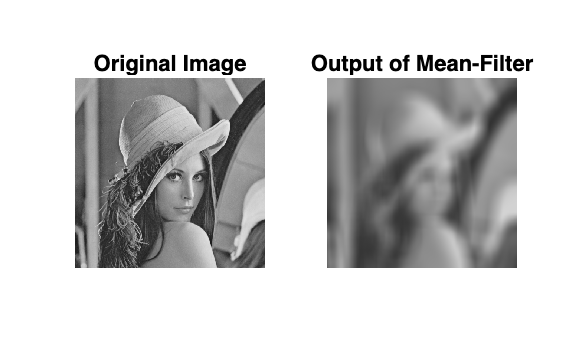

figure("Name","Mean Filter App");
set(gcf, 'Position', get (0, 'ScreenSize'));
subplot(121) ,imshow(img), title('Original Image');
subplot(122), imshow(output) ,title('Output of Mean-Filter');